# Cosyne 2020 Neurodata Without Borders Tutorial

## This tutorial

Create fake data for a hypothetical extracellular electrophysiology experiment with a freely moving animal. The types of data we will convert are:

- Animal position

- LFP

- Spike times

- Trials

- Subject (species, strain, age, .etc) 

## Installing matnwb

If you are in the tutorial using MATLAB Online, just access matnwb from the shared MATLAB Drive folder, and add that folder to your path. 

If participating from your own machine, use this code to install mat from source.

%{
!git clone https://github.com/NeurodataWithoutBorders/matnwb.git
cd matnwb
addpath(genpath(pwd));
generateCore();
%}

## Setup nwbfile

nwb = NwbFile( ...
   	'session_description', 'mouse in open exploration',...
    'identifier', 'Mouse5_Day3', ...
   	'session_start_time', datetime(2018, 4, 25, 2, 30, 3), ...
    'experimenter', 'My Name', ... % optional
    'session_id','session_1234', ... % optional
    'institution','University of My Institution', ... % optional
    'related_publications','DOI:10.1016/j.neuron.2016.12.011'); % optional
nwb

## Subject information

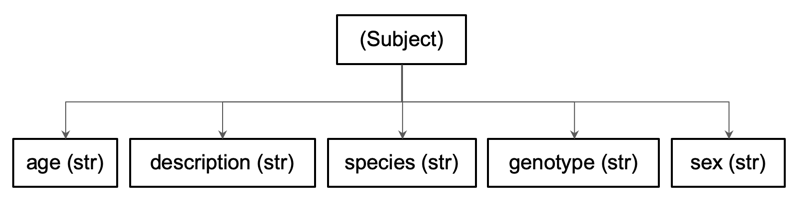

subject = types.core.Subject( ...
    'age', 'P109D', ...
    'description', 'mouse 5', ...
    'species', 'Mus musculus', ...
    'sex', 'M');
nwb.general_subject = subject

## Position

The `Position` object is a `NWBContainer` that holds one or more `SpatialSeries`.

`SpatialSeries `are a subclass of `TimeSeries.` `TimeSeries` is is a common base class for measurements sampled over time, and provides fields for data and time (regularly or irregularly sampled).

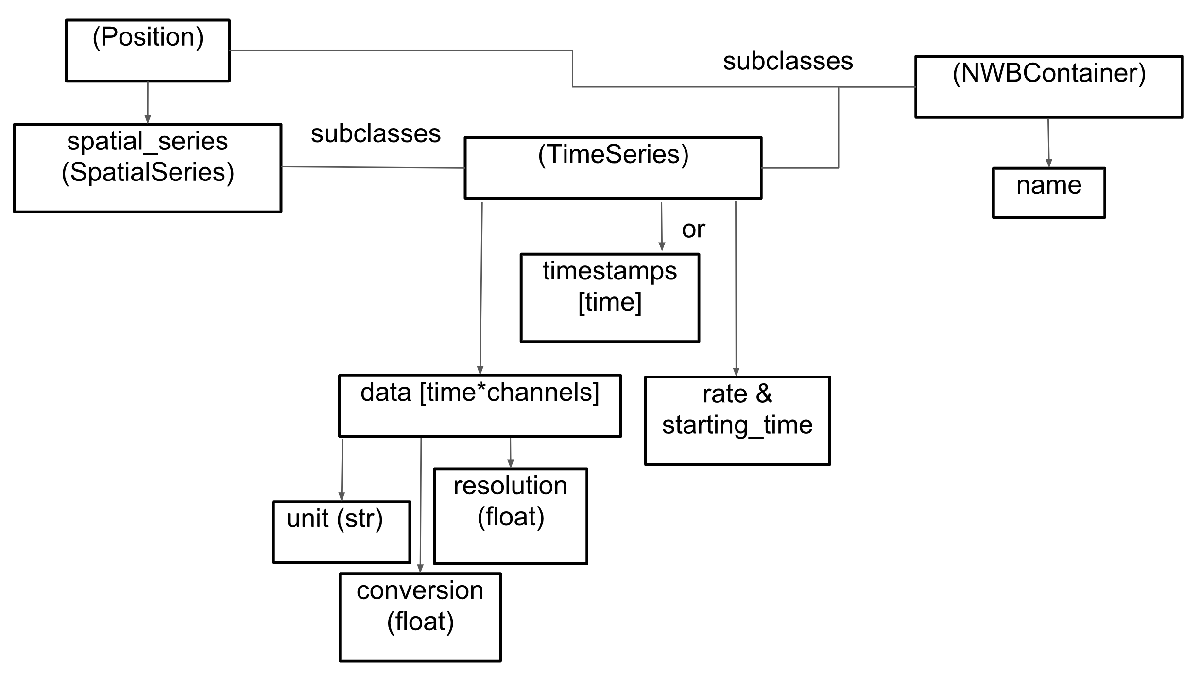 

Here, we put a `SpatialSeries` object called `'position'` in a `Position` object, and put that in a  `ProcessingModule` named `'behavior'`.

position_data = [linspace(0,10,100); linspace(1,8,100)]';

position_ts = types.core.SpatialSeries( ...
   	'data', position_data, ...
   	'reference_frame', 'unknown', ...
   	'data_conversion', 1.0, ...
    'data_resolution', NaN, ...
   	'timestamps', linspace(0, 100)/200)

behavior_mod = types.core.ProcessingModule( ...
    'description',  'contains behavioral data');

Position = types.core.Position('data', position_ts);
behavior_mod.nwbdatainterface.set(...
    'Position', Position);

nwb.processing.set('behavior', behavior_mod);

## Test write

nwbExport(nwb, 'ecephys_tutorial.nwb')

## Trials

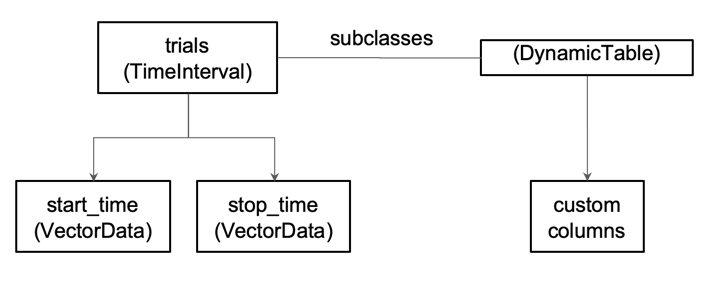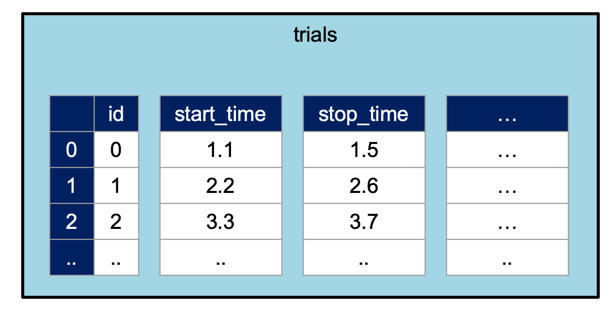

`DynamicTable` objects are used to store tabular meta-data throughout NWB, including electrodes, and sorted units. They offer flexibility for tabular data by allowing required columns, optional columns, and custom columns.

Trials are stored in a `TimeInterval` object which subclasses  DynamicTable. Here, we are adding `'correct'`, which will be a `boolean` array.

trials = types.core.TimeIntervals( ...
    'colnames', {'start_time', 'stop_time', 'correct'}, ...
    'description', 'trial data and properties', ...
    'id', types.core.ElementIdentifiers('data', 0:2), ...
    'start_time', types.core.VectorData('data', [.1, 1.5, 2.5], ...
   	'description','start time of trial'), ...
    'stop_time', types.core.VectorData('data', [1., 2., 3.], ...
   	'description','end of each trial'), ...
    'correct', types.core.VectorData('data', [false, true, false], ...
   	'description', 'my description'))
nwb.intervals_trials = trials;

## Extracellular electrophysiology

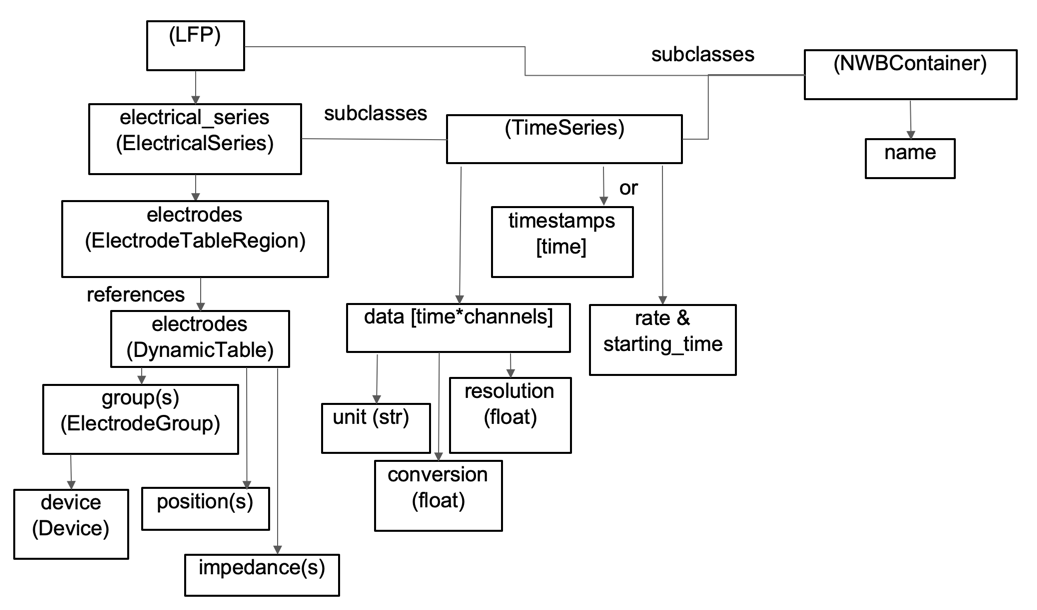

`ElectricalSeries` are `TimeSeries` and are stored in an `LFP` object. 

In addition to all of the `TimeSeries` fields, `ElectricalSeries` also has an electrodes field which is a reference to the electrodes table. In order to create an `ElectricalSeries`, you need to first create an electrodes table.

## Electrode table

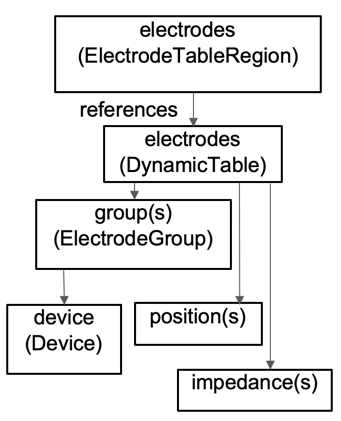

Extracellular electrodes are stored in a `electrodes` table, which is also a `DynamicTable`. `electrodes` has several required fields: x, y, z, impedence, location, filtering, and electrode_group. Here, we also demonstate another method for creating `DynamicTable`s, by first creating a MATLAB native Table object and then calling `util.table2nwb`.

shank_channels = [3, 4];
variables = {'x', 'y', 'z', 'imp', 'location', 'filtering', 'group', 'label'};
device_name = 'implant';
nwb.general_devices.set(device_name, types.core.Device());
device_link = types.untyped.SoftLink(['/general/devices/' device_name]);
for ishank = 1:length(shank_channels)
    nelecs = shank_channels(ishank);
    group_name = ['shank' num2str(ishank)];
    nwb.general_extracellular_ephys.set(group_name, ...
        types.core.ElectrodeGroup( ...
        'description', ['electrode group for shank' num2str(ishank)], ...
   	    'location', 'brain area', ...
   	    'device', device_link));
    group_object_view = types.untyped.ObjectView( ...
       	['/general/extracellular_ephys/' group_name]);
    for ielec = 1:length(nelecs)
        if ishank == 1 && ielec == 1
            tbl = table(NaN, NaN, NaN, NaN, {'unknown'}, {'unknown'}, ...
                group_object_view, {[group_name 'elec' num2str(ielec)]}, ...
                'VariableNames', variables);
       	else
            tbl = [tbl; {NaN, NaN, NaN, NaN, 'unknown', 'unknown', ...
                group_object_view, [group_name 'elec' num2str(ielec)]}];
       	end
    end
end
electrode_table = util.table2nwb(tbl, 'all electrodes');
nwb.general_extracellular_ephys_electrodes = electrode_table;

## Links

In the above loop, we create `ElectrodeGroup` objects. The `electrodes` table then uses an `ObjectView` in each row to link to the corresponding `ElectrodeGroup` object. An `ObjectView` is an object that allow you to create a link from one neurodata type referencing another. 

In order to create our `ElectricalSeries` object, we will also need to create a `DynamicTableRegion` of `electrodes`. A `DynamicTableRegion` is a type of link that allows you to reference specific rows of a `DynamicTable`.

electrodes_object_view = types.untyped.ObjectView( ...
    '/general/extracellular_ephys/electrodes');

electrode_table_region = types.core.DynamicTableRegion( ...
    'table', electrodes_object_view, ...
    'description', 'all electrodes', ...
    'data', [0 height(tbl)-1]');

## LFP

`LFP` is another `MultiContainerInterface`. It holds one or more  `ElectricalSeries` objects, which are `TimeSeries`. Here, we put an  `ElectricalSeries` named `'lfp'` in an `LFP` object, in a `ProcessingModule` named  `'ecephys'`. Note that we are using the `DynamicTableRegion` to match this signal up with electrodes. This allows you to annotate recordings from a subset of available electrodes.

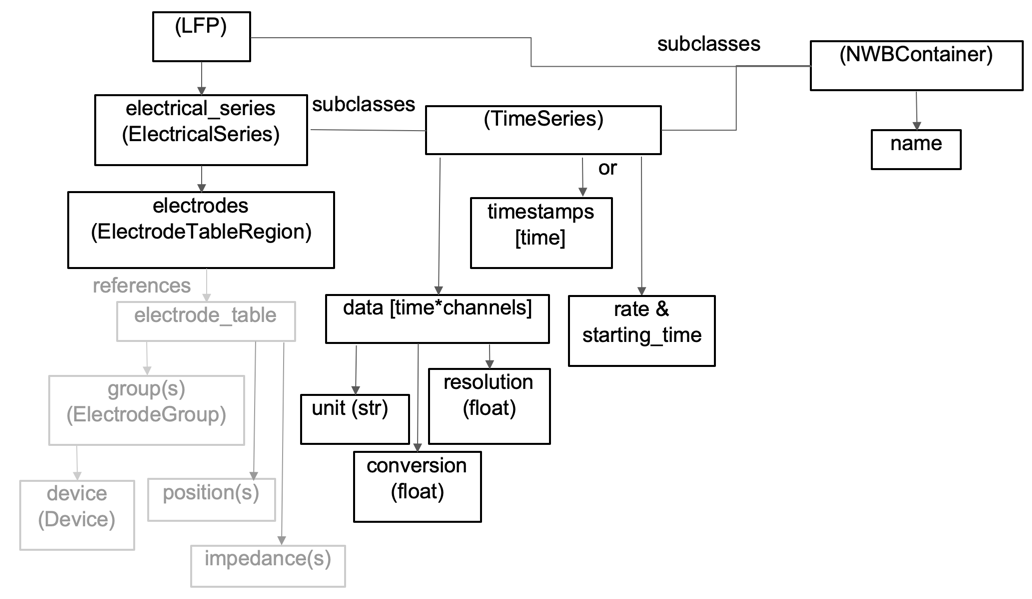

electrical_series = types.core.ElectricalSeries( ...
    'starting_time', 0.0, ... % seconds
    'starting_time_rate', 200., ... % Hz
    'data', randn(7, 100), ...
    'electrodes', electrode_table_region, ...
    'data_unit', 'V');

ecephys_module = types.core.ProcessingModule(...
    'description', 'extracellular electrophysiology');

ecephys_module.nwbdatainterface.set('LFP', types.core.LFP( ...
    'lfp', electrical_series));
nwb.processing.set('ecephys', ecephys_module);

## Spike times

#### Ragged arrays

Spike times are stored in another `DynamicTable` of subtype `Units`. The default `Units` table is at `/units` in the HDF5 file. You can add columns to the `Units` table just like you did for `electrodes` and `trials`. Here, we generate some random spike data and populate the table. 

Spike times are an example of a ragged array- it's like a matrix, but each row has a different number of elements. We can represent this type of data as an indexed column of the units `DynamicTable`. These indexed columns have two components, the vector data object that holds the data and the vector index object that holds the indices in the vector that indicate the row breaks. 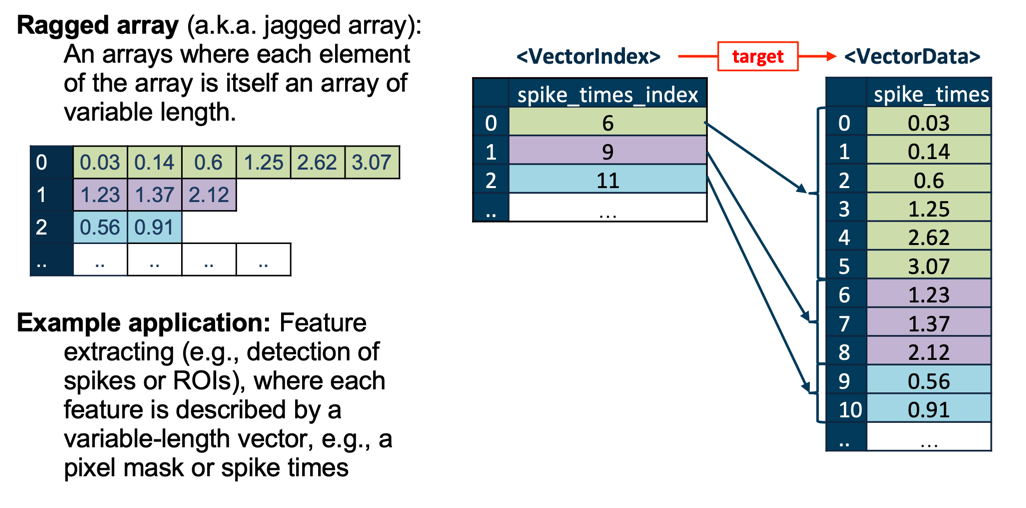You can use the convenience function `util.create_indexed_column` to create these objects.

spikes = {};
num_cells = 10;
firing_rate = 20;
for ishank = 1:num_cells
    for iunit = 1:poissrnd(20)
        spikes{end+1} = cumsum(exprnd(1/firing_rate));
    end
end

[spike_times_vector, spike_times_index] = util.create_indexed_column( ...
    spikes, '/units/spike_times');

nwb.units = types.core.Units( ...
    'colnames', {'spike_times'}, ...
    'description', 'units table', ...
    'id', types.core.ElementIdentifiers( ...
    'data', int64(0:length(spikes) - 1)), ...
    'spike_times', spike_times_vector, ...
    'spike_times_index', spike_times_index);

## Write the file

nwbExport(nwb, 'ecephys_tutorial.nwb')

## Reading NWB data

Data arrays are read passively from the file. Calling `TimeSeries.data` does not read the data values, but presents an HDF5 object that can be indexed to read data. This allows you to conveniently work with datasets that are too large to fit in RAM all at once. Index this array with the `load` method. 

`load` with no input arguments reads the entire dataset:

nwb2 = nwbRead('ecephys_tutorial.nwb')

nwb2.processing.get('ecephys').nwbdatainterface. ...
   	get('LFP').electricalseries.get('lfp').data.load;

## Accessing data regions

It is often preferable to read only a portion of the data. To do this, use the `load` method with input arguments. The following takes elements 1:5 and 1:10 from the data we have written.

% read section of LFP
nwb2.processing.get('ecephys'). ...
    nwbdatainterface.get('LFP'). ...
    electricalseries.get('lfp'). ...
    data.load([1,1],[5,10])

% You can use the utility function |util.read_indexed_column| to read
util.read_indexed_column( ...
    nwb.units.spike_times_index, nwb.units.spike_times, 1)